## MATLAB和C混合编程

例：

将avg.c代码编辑好放到matlab目录下

在命令行输入：

mex -setup;

错误使用 mex
找不到支持的编译器。您可以安装免费提供的 MinGW-w64 C/C++ 编译器；请参阅安装 MinGW-w64 编译器。有关更多选项，请访问 <a href="https://www.mathworks.com/support/compilers">https://www.mathworks.com/support/compilers</a>。

mex avg.c;
[mean, var]=avg([1 2 3 4 5]);

## 求偏导

### diff(z, x)

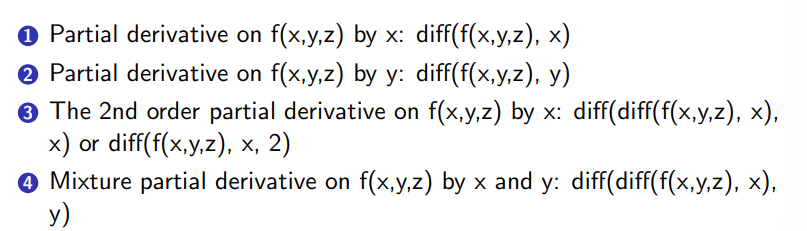

例：

syms x y
z = x^2 + y^2;
diff(z,x)           % x偏导

$$ans = 2\,x$$

diff(z,y)           % y偏导

$$ans = 2\,y$$

diff(diff(z,x), x)  % x二次偏导

$$ans = 2$$

diff(diff(z,x), y)  % x偏导的y偏导

$$ans = 0$$

例1.

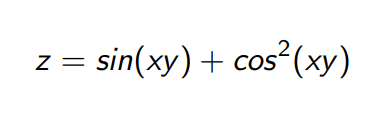

z=sin(x*y)+(cos(x*y))^2;
dfx=diff(z,x)

$$dfx = y\,\cos\left(x\,y\right)-2\,y\,\cos\left(x\,y\right)\,\sin\left(x\,y\right)$$

dfy=diff(z,y)

$$dfy = x\,\cos\left(x\,y\right)-2\,x\,\cos\left(x\,y\right)\,\sin\left(x\,y\right)$$

dfy=diff(z,x,2)

$$dfy = -2\,y^{2}\,{\cos\left(x\,y\right)}^{2}+2\,y^{2}\,{\sin\left(x\,y\right)}^{2}-y^{2}\,\sin\left(x\,y\right)$$

dfxy=diff(diff(z,x),y)

$$dfxy = -2\,x\,y\,{\cos\left(x\,y\right)}^{2}-2\,\cos\left(x\,y\right)\,\sin\left(x\,y\right)+\cos\left(x\,y\right)+2\,x\,y\,{\sin\left(x\,y\right)}^{2}-x\,y\,\sin\left(x\,y\right)$$

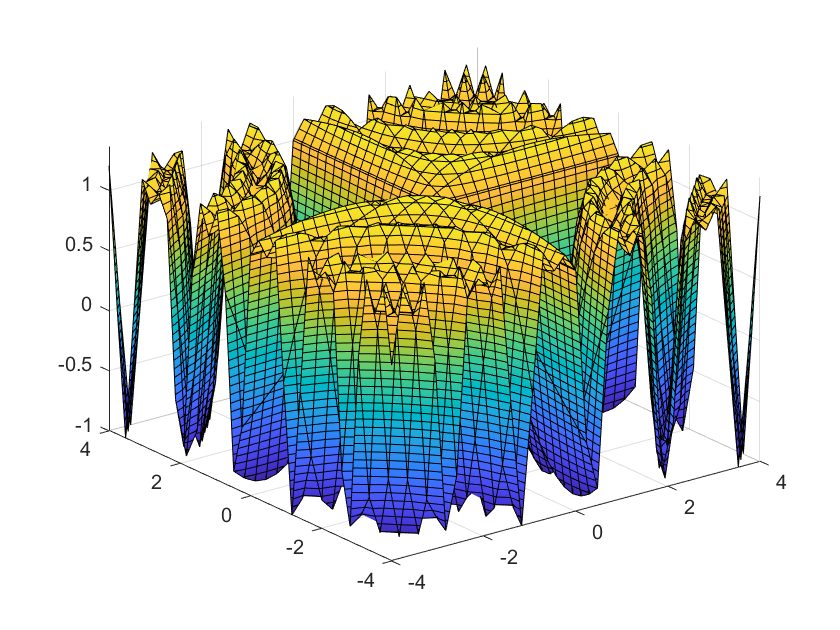

syms x y z
fimplicit3(sin(x*y)+(cos(x*y))^2-z,[-4 4 -4 4 -1 1.5])

## 绘制等高线

### contour(x, y, z, height);

例1：

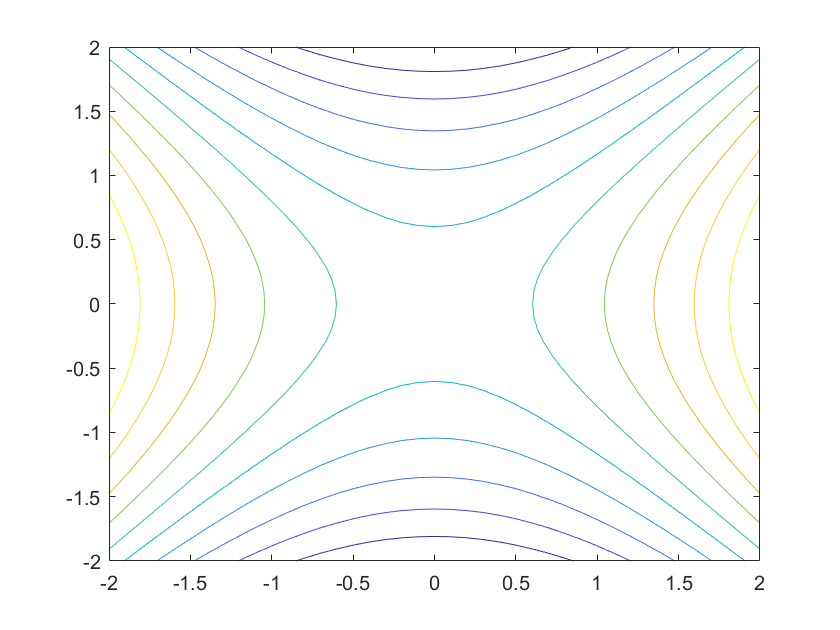

[x,y]=meshgrid(-2:0.1:2,-2:0.1:2);
z=x.^2-y.^2+0.5; 
contour(x, y, z, 10);

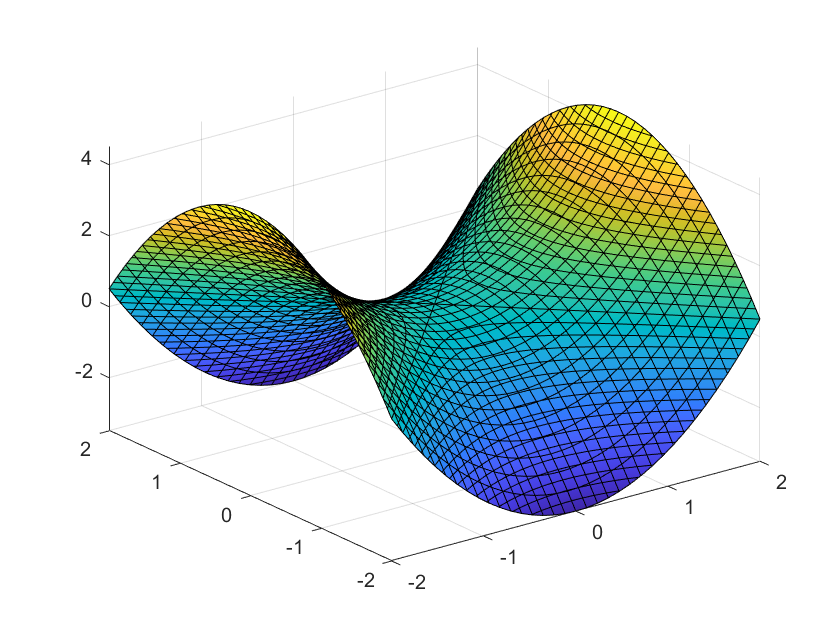

syms x y z
interval=[-2 2 -2 2 -3.5 4.5];
fimplicit3(x^2-y^2+0.5-z,interval)

## 方程组的解

### [x,y]=solve(式子1，式子2，x，y）

例1：

syms x y
[x,y] = solve(x^2+x*y+y-3,x^2-4*x+3, x, y)

$$x = \left(\begin{array}{c} 1\\ 3 \end{array}\right)$$

$$y = \left(\begin{array}{c} 1\\ -\frac{3}{2} \end{array}\right)$$

## 综合运用

### 求切平面

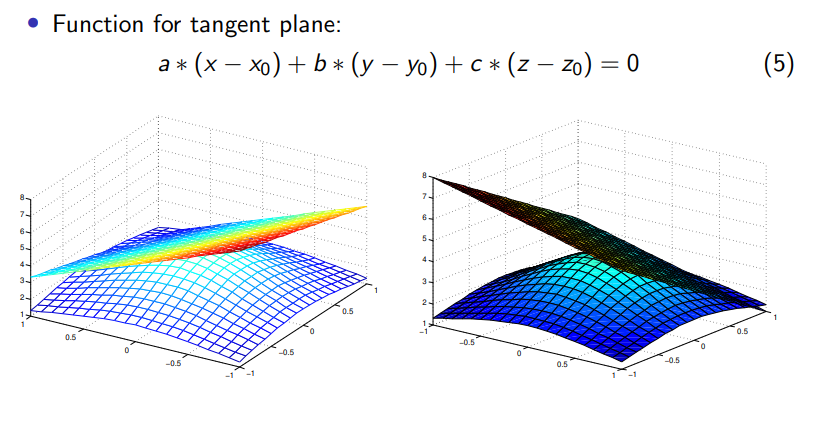

**a,b,c分别为F对x,y,z的偏导在x0,y0,z0处的取值**

例1.

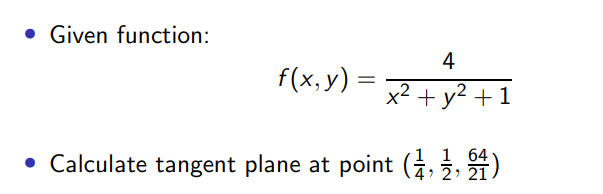

**求f在点(1/4,1/2,64/21)处的切平面**

syms x y z
F = 4/(x^2+y^2+1)-z; % 此版MATLAB不用加引号
f = diff(F,x);       % 求偏导
g = diff(F,y);
h = diff(F,z);
x = 1/4; y=1/2; z=64/21

z = 3.0476

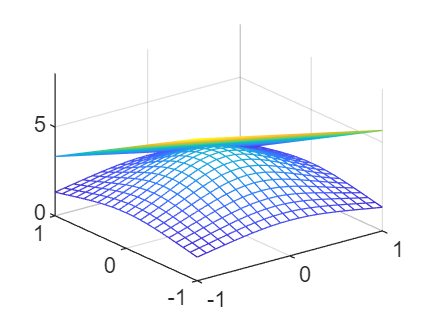

a = eval(f);         % 求偏导的值
b = eval(g);
c = eval(h);
[x,y] = meshgrid(-1:0.1:1,-1:0.1:1);
z1=-1*(a*(x-1/4)+b*(y-1/2))/c+64/21;   % c*z=-a*(x-x0)+b*(y-y0))+z0
z2=4*(x.^2+y.^2+1).^(-1);              % 写成右边为0的等式形式
mesh(x, y, z1); 
hold on;
mesh(x, y, z2);

### 求多元函数的极值

#### 例1 δ判极值

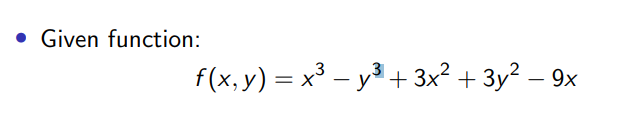

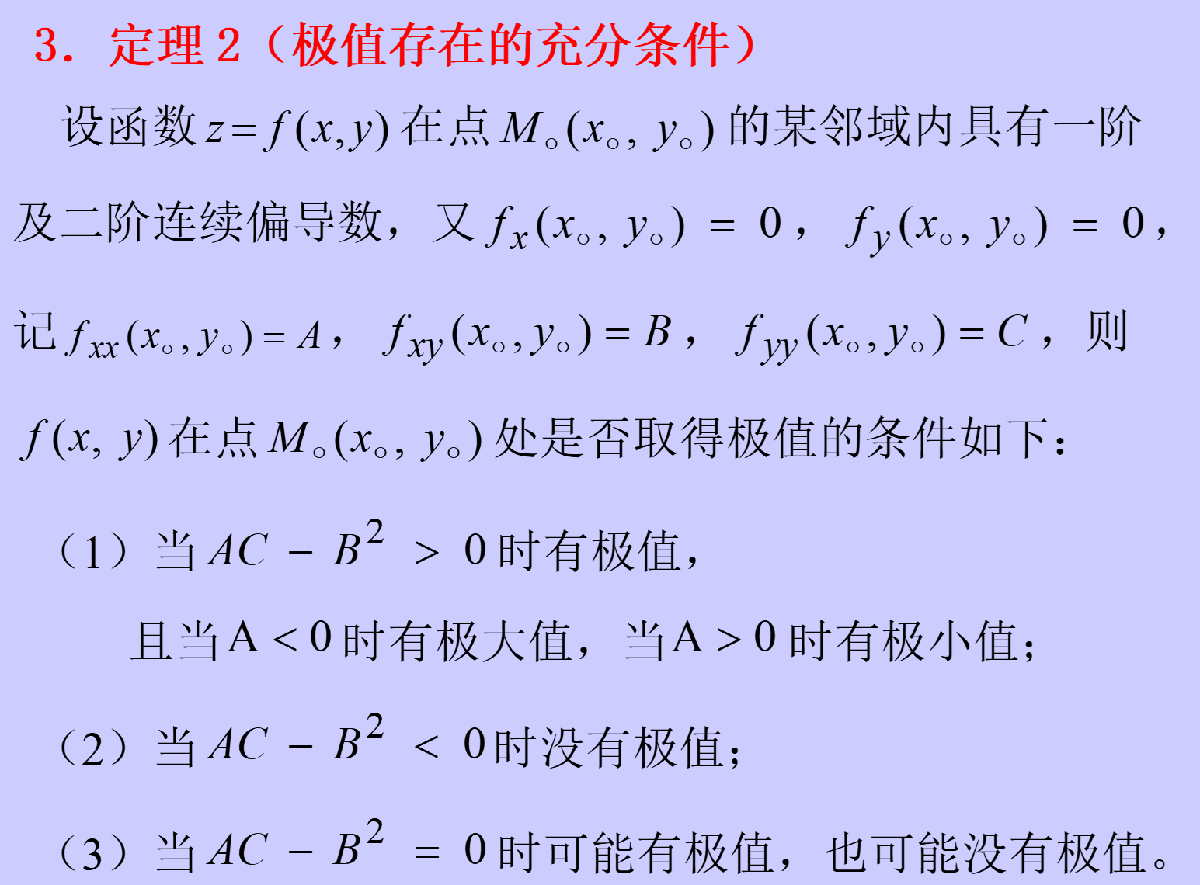

已知极值点的x,y偏导都为0，反之则不然

故，求出所有x,y偏导都为0的点，找出极值

clear;syms x y;
f=x^3-y^3+3*x^2+3*y^2-9*x

$$f = x^{3}+3\,x^{2}-9\,x-y^{3}+3\,y^{2}$$

dx=diff(f,x);
dy=diff(f,y); 

x0=roots([3,6,-9])      % 一阶偏导的根

x0 =    -3.0000
    1.0000


y0=roots([-3,6,0])

y0 =      0
     2



dxx=diff(f,x,2);
dyy=diff(f,y,2);
dxy=diff(diff(f,x),y);
H=(dxy)^2-(dxx)*(dyy);% δ判根，若>0有极值

x=-3;y=0;%排列组合求极值
h1=eval(H);
a1=eval(dxx);
f1=eval(f);

x=-3;y=2;
h2=eval(H);
a2=eval(dxx);
f2=eval(f);

x=1;y=0;
h3=eval(H);
a3=eval(dxx);
f3=eval(f);

x=1;y=2;
h4=eval(H);
a4=eval(dxx);
f4=eval(f);

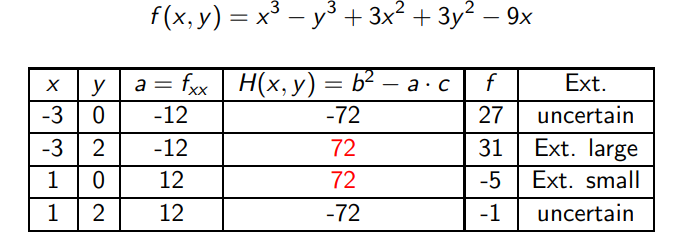

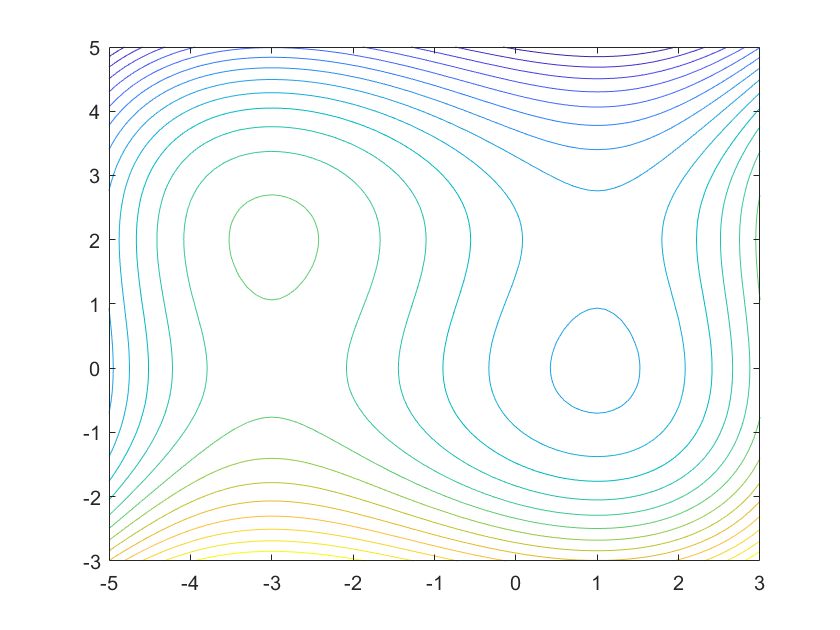

clf;
[x,y]=meshgrid(-5:0.1:3,-3:0.1:5);
z=x.^3-y.^3+3*x.^2+3*y.^2-9*x;
contour(x, y, z, 20);  % 两个圈圈说明有两个答案

#### 例2 拉格朗日极值法

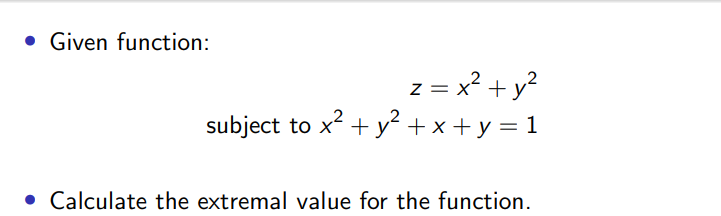

计算z的极值，而x,y由下个等式限制

转换为拉格朗日求极值形式：

计算过程:

syms x y r
g=x^2+y^2;%所求函数
h=x^2+y^2+x+y-1;
la=g+r*h;

lx=diff(la,x)

$$lx = 2\,x+r\,\left(2\,x+1\right)$$

ly=diff(la,y)

$$ly = 2\,y+r\,\left(2\,y+1\right)$$

lr=diff(la,r)

$$lr = x^{2}+x+y^{2}+y-1$$


[x,y,r]=solve(lx,ly,lr,x,y,r)

$$x = \left(\begin{array}{c} -\frac{\sqrt{3}}{2}-\frac{1}{2}\\ \frac{\sqrt{3}}{2}-\frac{1}{2} \end{array}\right)$$

$$y = \left(\begin{array}{c} -\frac{\sqrt{3}}{2}-\frac{1}{2}\\ \frac{\sqrt{3}}{2}-\frac{1}{2} \end{array}\right)$$

$$r = \left(\begin{array}{c} -\frac{\sqrt{3}}{3}-1\\ \frac{\sqrt{3}}{3}-1 \end{array}\right)$$


x=sqrt(3)/2-1/2

x = 0.3660

y=sqrt(3)/2-1/2

y = 0.3660

eval(g)

ans = 0.2679


x=-sqrt(3)/2-1/2

x = -1.3660

y=sqrt(3)/2-1/2

y = 0.3660

eval(g)

ans = 2


x=sqrt(3)/2-1/2

x = 0.3660

y=-sqrt(3)/2-1/2

y = -1.3660

eval(g)

ans = 2


x=-sqrt(3)/2-1/2

x = -1.3660

y=-sqrt(3)/2-1/2

y = -1.3660

eval(g)

ans = 3.7321

三维图可视化:

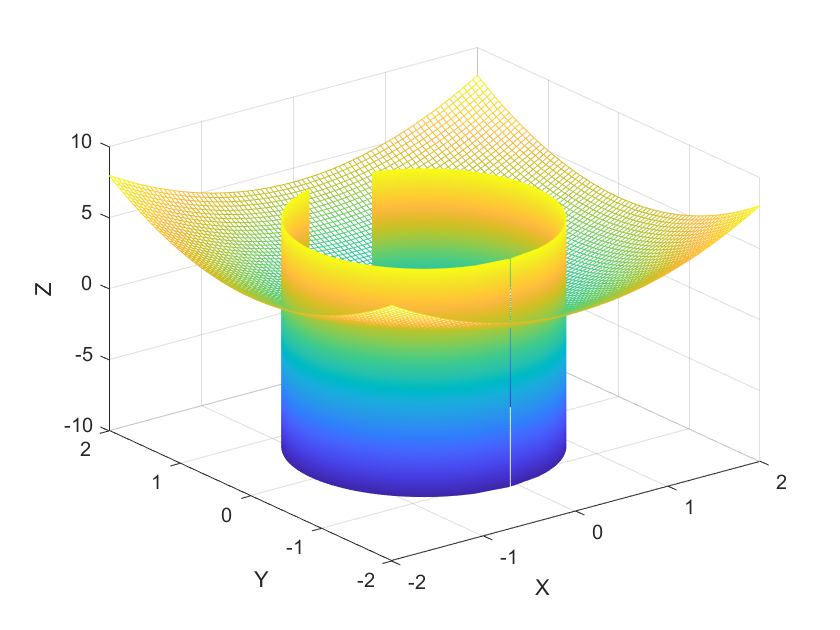

clf;
clear;
[X, Y] = meshgrid(-2:0.05:2,-2:0.05:2);
Z = X.^2+Y.^2;
mesh(X,Y,Z); hold on;
xlabel('X');
ylabel('Y');
zlabel('Z');
% syms x y;
% x = solve( x^2+y^2+x+y-1,y)
[Y, Z] = meshgrid(-1.7247:0.05:0.725, -8:0.05:8);
X1 = - (- 4*Y.^2 - 4*Y + 5).^(1/2)/2 - 1/2;  
X2 = (- 4*Y.^2 - 4*Y + 5).^(1/2)/2 - 1/2;
mesh(X1, Y, Z);
hold on;
mesh(X2, Y, Z);

等高图可视化：

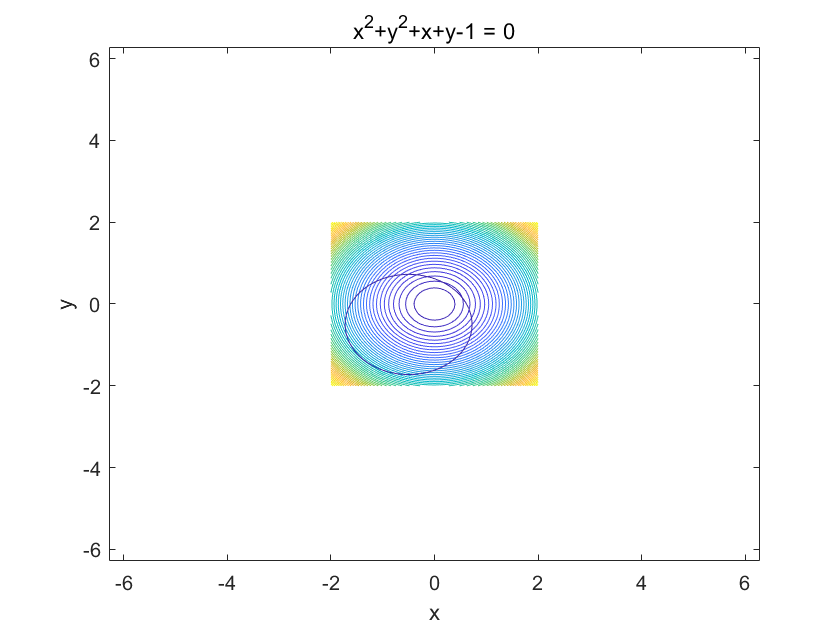

clf;
[x,y]=meshgrid(-2:0.1:2,-2:0.1:2);
z=x.^2+y.^2;
contour(x,y,z,50); hold on;
ezplot('x^2+y^2+x+y-1');%画限制函数截面图

#### 例3 Exercise

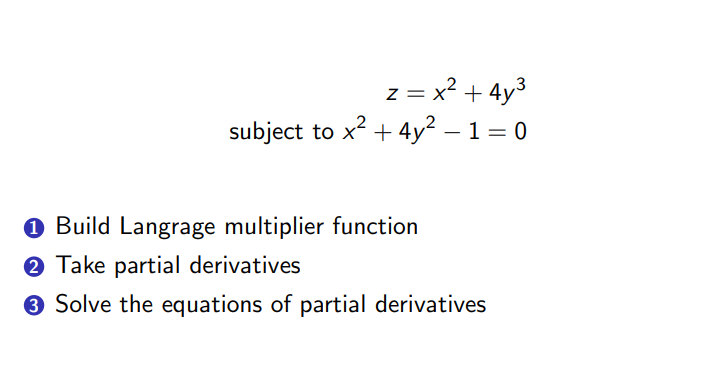

计算过程：

syms x y r
g = x^2+4*y^3;
h=x^2+4*y^2-1;
lag=g+r*h

$$lag = r\,\left(x^{2}+4\,y^{2}-1\right)+x^{2}+4\,y^{3}$$


lx = diff(lag, x)

$$lx = 2\,x+2\,r\,x$$

ly = diff(lag, y)

$$ly = 12\,y^{2}+8\,r\,y$$

lr = diff(lag, r)

$$lr = x^{2}+4\,y^{2}-1$$


[solx,soly,solr] = solve(lx, ly, lr, x, y, r)

$$solx = \left(\begin{array}{c} -1\\ 1\\ 0\\ 0\\ -\frac{\sqrt{7}\,\mathrm{i}}{3}\\ \frac{\sqrt{7}\,\mathrm{i}}{3} \end{array}\right)$$

$$soly = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{2}\\ -\frac{1}{2}\\ \frac{2}{3}\\ \frac{2}{3} \end{array}\right)$$

$$solr = \left(\begin{array}{c} -1\\ -1\\ -\frac{3}{4}\\ \frac{3}{4}\\ -1\\ -1 \end{array}\right)$$

solutions=[solx,soly,solr]

$$solutions = \left(\begin{array}{ccc} -1 & 0 & -1\\ 1 & 0 & -1\\ 0 & \frac{1}{2} & -\frac{3}{4}\\ 0 & -\frac{1}{2} & \frac{3}{4}\\ -\frac{\sqrt{7}\,\mathrm{i}}{3} & \frac{2}{3} & -1\\ \frac{\sqrt{7}\,\mathrm{i}}{3} & \frac{2}{3} & -1 \end{array}\right)$$

可视化：

clf;
clear;
[X, Y] = meshgrid(-2:0.05:2,-2:0.05:2);
Z = X.^2+4*Y.^3;
mesh(X,Y,Z); hold on;
xlabel('X');
ylabel('Y');
zlabel('Z');
%syms x y;

%x = solve('x^2+4*y^2-1','x')
[Y, Z] = meshgrid(-0.5:0.05:0.5,-8:0.05:8);
X1 = sqrt(1-4*Y.^2)

X1 =          0    0.4359    0.6000    0.7141    0.8000    0.8660    0.9165    0.9539    0.9798    0.9950    1.0000    0.9950    0.9798    0.9539    0.9165    0.8660    0.8000    0.7141    0.6000    0.4359         0
         0    0.4359    0.6000    0.7141    0.8000    0.8660    0.9165    0.9539    0.9798    0.9950    1.0000    0.9950    0.9798    0.9539    0.9165    0.8660    0.8000    0.7141    0.6000    0.4359         0
         0    0.4359    0.6000    0.7141    0.8000    0.8660    0.9165    0.9539    0.9798    0.9950    1.0000    0.9950    0.9798    0.9539    0.9165    0.8660    0.8000    0.7141    0.6000    0.4359         0
         0    0.4359    0.6000    0.7141    0.8000    0.8660    0.9165    0.9539    0.9798    0.9950    1.0000    0.9950    0.9798    0.9539    0.9165    0.8660    0.8000    0.7141    0.6000    0.4359         0
         0    0.4359    0.6000    0.7141    0.8000    0.8660    0.9165    0.9539    0.9798    0.9950    1.0000    0.9950    0.9798    0.9539    0.9165 

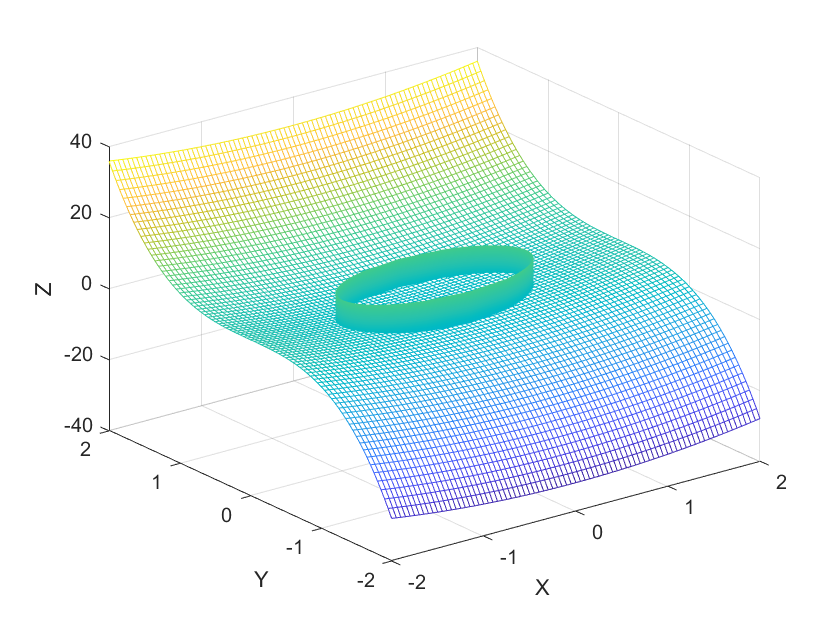

X2 = -sqrt(1-4*Y.^2);
mesh(X1, Y, Z);
hold on;
mesh(X2, Y, Z);

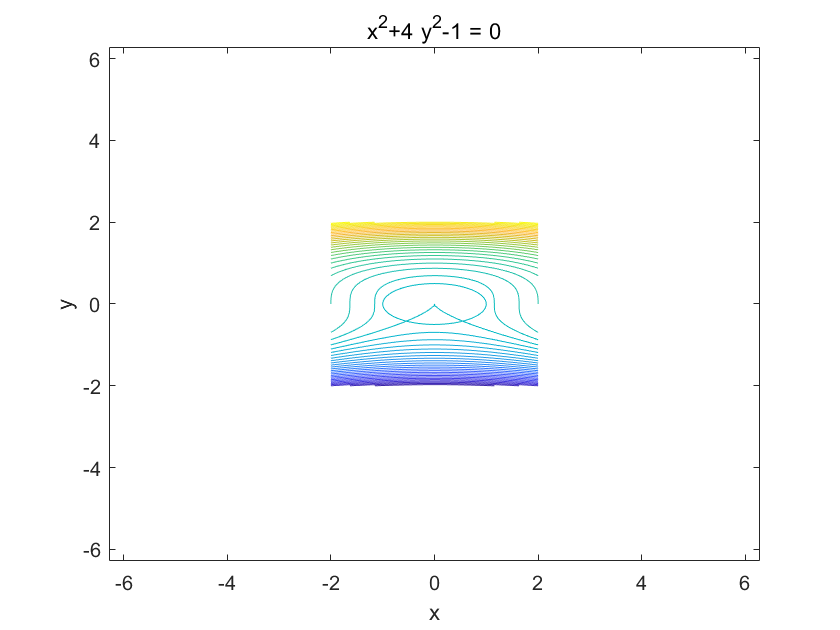

clf;
[x,y]=meshgrid(-2:0.05:2,-2:0.05:2);
z=x.^2+4*y.^3;
contour(x,y,z,50); hold on;
ezplot('x^2+4*y^2-1');%画限制函数截面图